Define filter parameters:

Fpass = 20;
Fstop = 22;
Fs = 60;
Rp = 0.5;
Rs = 70;

Wp = 2*Fpass*pi;
Ws = 2*Fstop*pi;

Define minimal order and construct analog filter

[n,Wp] = cheb1ord(Wp,Ws,Rp,Rs,'s');
[sb,sa] = cheby1(n,Rp,Wp,'s');

Create a digital prototype of analog filter

[zb,za] = impinvar(sb,sa,Fs);

Calculate impulse responses of filters

$H{\left(s\right)}=\sum_k \frac{r_k }{s-p_k }$→$h{\left(t\right)}=\sum_k r_k e^{p_k t}$

[r,p] = residue(sb,sa);   %direct term of a Partial Fraction Expansion
st = linspace(0,100/Fs,1000);
sh = real(r.'*exp(p.*st)/Fs);     %analog filter impulse response

[zh,zt] = impz(zb,za,[],Fs);  %digital filter impulse invariance

Plot impulse responses

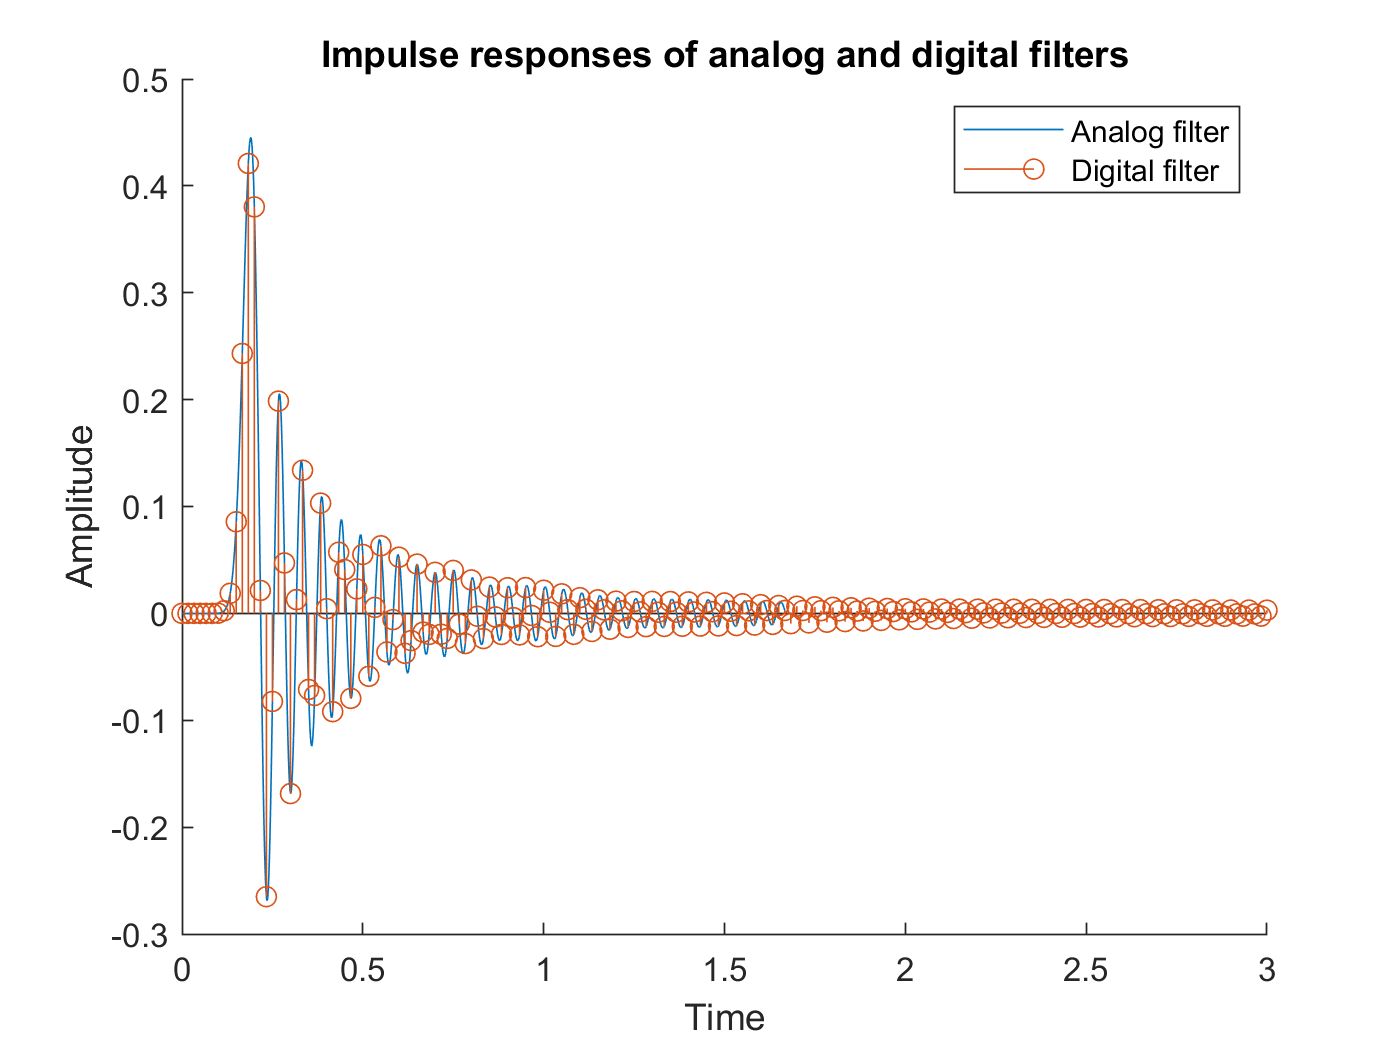

figure(1);  clf; hold on;
title('Impulse responses of analog and digital filters');
plot(st,sh); stem(zt,zh);
legend('Analog filter','Digital filter'),xlim([0 3]);
ylabel('Amplitude'); xlabel('Time');

Calculate impulse responses of filters

[zh,zw] = freqz(zb,za);
[sh,sw] = freqs(sb,sa,zw*Fs);

%convert to dB scale
zh_db = 20*log10(abs(zh));
sh_db = 20*log10(abs(sh));

Plot frequency responses

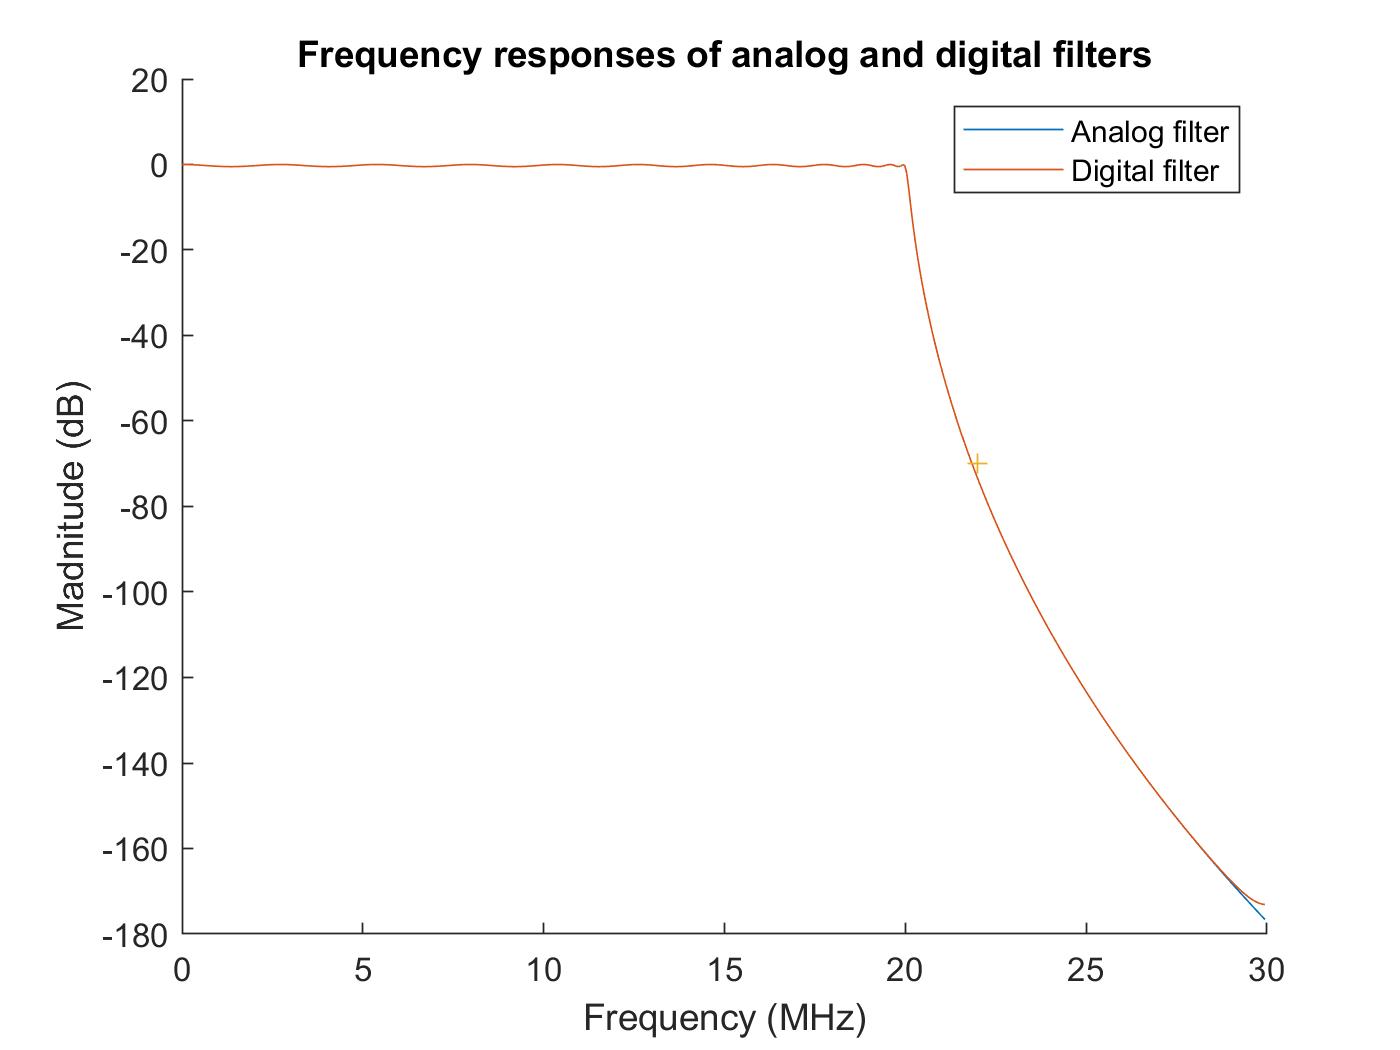

figure(2); clf; hold on;
title('Frequency responses of analog and digital filters');
plot(0.5*sw/pi,sh_db);
plot(0.5*Fs*zw/pi,zh_db);
plot(22,-70,'+');
legend('Analog filter','Digital filter');
ylabel('Madnitude (dB)'); xlabel('Frequency (MHz)');